%OLS

N = 20;  % Number of observations
R = 200;  % Number of realizations
X1 = randn(N,1);
X2 = randn(N,1);
phi = [X1 X2 ones(N,1)];
Y_data = zeros(N, R);   

n_iter = 10000;
lr = 0.01;

% Generate R realizations of the data
for r = 1:R
    e = randn(N, 1);
    Y_gen = 3 * X1 + 5 * X2 + e;
    Y_data(:, r) = Y_gen;
end

theta_true = [3; 5; 0];  % True parameter values

[MSE, RB, MAD, avg_theta] = OLS(Y_data, phi, N, R, n_iter, lr, theta_true);

disp('Average Estimated Parameters using OLS:');

Average Estimated Parameters using OLS:


disp(avg_theta);

    2.9965
    4.9961
    0.0162




disp('Mean Square Error (MSE) for OLS:');

Mean Square Error (MSE) for OLS:


disp(MSE);

    0.0274
    0.0378
    0.0559




disp('Robust Bias (RB): for OLS');

Robust Bias (RB): for OLS


disp(RB);

    0.0083
    0.0081
    0.0171




disp('Median Absolute Deviation (MAD) for OLS:');

Median Absolute Deviation (MAD) for OLS:


disp(MAD);

    0.1170
    0.1279
    0.1481



function [MSE, RB, MAD, avg_theta] = OLS(Y_data, phi, N, R, n_iter, lr, theta_true)
    % Initialize storage for parameter vectors and gradients
    theta_all = zeros(3, R);
    grad_all = zeros(3, R);

    % Perform parameter estimation for each realization
    for r = 1:R
        Y = Y_data(:, r);
        theta = zeros(3, 1);
        grad = zeros(3, 1);

        % Perform Gradient Descent (OLS estimation)
        for iter = 1:n_iter
            % Compute predicted values based on current parameters (theta)
            y_pred = phi * theta;

            % Compute gradient of the loss function (MSE) with respect to theta
            grad = -1 * phi' * (Y - y_pred) / N;

            % Update parameters (theta) using gradient descent
            theta = theta - lr * grad;
        end

        % Store the parameter vector (theta) and gradient for the current realization
        theta_all(:, r) = theta; 
        grad_all(:, r) = grad; 
    end

    % Compute average parameter vector and gradient across realizations
    avg_theta = mean(theta_all, 2);
    avg_grad = mean(grad_all, 2);

    % Initialize storage for metrics
    MSE = zeros(3, 1);   
    RB = zeros(3, 1);    
    MAD = zeros(3, 1);   

    % Compute metrics for each parameter across all realizations
    for i = 1:3 
        % Extract estimated parameter values (theta_i) across all realizations
        theta_est = theta_all(i, :);

        % Compute bias (mean) and variance of the estimated parameter values
        bias_theta = mean(theta_est) - theta_true(i);
        var_theta = var(theta_est);

        % Compute Mean Square Error (MSE) for the parameter
        MSE(i) = bias_theta^2 + var_theta;

        % Compute Robust Bias (RB) for the parameter
        RB(i) = median(theta_est) - theta_true(i);

        % Compute Median Absolute Deviation (MAD) for the parameter
        MAD(i) = median(abs(theta_est - theta_true(i)));
    end
end

%LMS
beta_true = [3; 5; 0]; %True parameters

[MSE, RB, MAD, avg_beta] =LMS(Y_data, phi, N, R, n_iter, lr, beta_true);

disp('Average Estimated Parameters using LMS:');

Average Estimated Parameters using LMS:


disp(avg_beta);

    2.9550
    4.9320
    0.0484




disp('Mean Square Error (MSE) for LMS:');

Mean Square Error (MSE) for LMS:


disp(MSE);

    0.0622
    0.0941
    0.1131




disp('Robust Bias (RB) for LMS:');

Robust Bias (RB) for LMS:


disp(RB);

   -0.0326
   -0.0446
    0.0379




disp('Median Absolute Deviation (MAD) for LMS:');

Median Absolute Deviation (MAD) for LMS:


disp(MAD);

    0.1926
    0.1741
    0.2219




function [MSE, RB, MAD, avg_beta] = LMS(Y_data, phi, N, R, n_iter, lr,theta_true)
    beta_all = zeros(3, R);
    grad_all = zeros(3, R);

    for r = 1:R
        Y = Y_data(:, r);
        beta = zeros(3, 1);
        gradient = zeros(3, 1);

        for iter = 1:n_iter
            y_pred = phi * beta;
            residuals = Y - y_pred;
            
            % Square the residuals
            squared_residuals = residuals.^2;
            huber_delta = median(squared_residuals);
            weights = min(1, huber_delta ./ squared_residuals);
        
            gradient = -1 * phi' * (weights .* residuals) / N;
            beta = beta - lr * gradient;
        end
        
        beta_all(:, r) = beta;  
        grad_all(:, r) = gradient;     
    end
    
    avg_beta = mean(beta_all, 2);
    avg_grad = mean(grad_all, 2); 

    MSE = zeros(3, 1);
    RB = zeros(3, 1);
    MAD = zeros(3, 1);

    for i = 1:3  
        beta_est = beta_all(i, :);
        
        % Compute bias (mean) and variance of the estimated parameter values
        bias_beta = mean(beta_est) - theta_true(i);
        var_beta = var(beta_est);

        % Compute Mean Square Error (MSE) for the parameter
        MSE(i) = bias_beta^2 + var_beta;

        % Compute Robust Bias (RB) for the parameter
        RB(i) = median(beta_est) - theta_true(i);

        % Compute Median Absolute Deviation (MAD) for the parameter
        MAD(i) = median(abs(beta_est - theta_true(i)));
    end
end

%LTS

gamma_true = [3; 5; 0]; %True parameters
q = floor(N/2 + 1);
[MSE, RB, MAD, avg_gamma] =LTS(Y_data, phi, N, R, n_iter, lr,q,gamma_true);

disp('Average Estimated Parameters using LTS:');

Average Estimated Parameters using LTS:


disp(avg_gamma);

    2.7850
    4.8234
   -0.5633




disp('Mean Square Error (MSE) for LTS:');

Mean Square Error (MSE) for LTS:


disp(MSE);

    0.1543
    0.1486
    0.3972




disp('Robust Bias (RB) for LTS:');

Robust Bias (RB) for LTS:


disp(RB);

   -0.1764
   -0.2060
   -0.5249




disp('Median Absolute Deviation (MAD) for LTS:');

Median Absolute Deviation (MAD) for LTS:


disp(MAD);

    0.2626
    0.2838
    0.5249



function [MSE, RB, MAD, avg_gamma] = LTS(Y_data, phi, N, R, n_iter, lr, q, gamma_true)
    gamma_all = zeros(3, R);
    grad_all = zeros(3, R);

    for r = 1:R
        Y = Y_data(:, r);
        gamma = zeros(3, 1);
        grad = zeros(3, 1);
        
        for iter = 1:n_iter
            % Compute residuals
            res = Y - phi * gamma;

            abs_res = abs(res);
            sorted_res = sort(abs_res);

            % Select the q smallest residuals
            threshold = sorted_res(q);
            inliers_mask = (res <= threshold);
            
            if sum(inliers_mask) > 0
                grad = -1 * phi' * (inliers_mask .* res) / N;
            else
                grad = zeros(size(gamma)) / N;
            end

            % Update parameters (gamma) using gradient descent
            gamma = gamma - lr * grad;
        end

        gamma_all(:, r) = gamma;  
        grad_all(:, r) = grad;     
    end

    avg_gamma = mean(gamma_all, 2);
    avg_grad = mean(grad_all, 2); 

    MSE = zeros(3, 1);
    RB = zeros(3, 1);
    MAD = zeros(3, 1);

    for i = 1:3  
        gamma_est = gamma_all(i, :);

        % Compute bias (mean) and variance of the estimated parameter values
        bias_gamma = mean(gamma_est) - gamma_true(i);
        var_gamma = var(gamma_est);

        % Compute Mean Square Error (MSE) for the parameter
        MSE(i) = bias_gamma^2 + var_gamma;

        % Compute Robust Bias (RB) for the parameter
        RB(i) = median(gamma_est) - gamma_true(i);

        % Compute Median Absolute Deviation (MAD) for the parameter
        MAD(i) = median(abs(gamma_est - gamma_true(i)));
    end
end

%Applying Custom OLS,LMS and LTS on Real Dataset

data=readtable("medical_insurance.csv");

age = data.age;
bmi = data.bmi;
charges = data.charges;
sex = data.sex;
smoker = data.smoker;
region = data.region;

% Normalize numeric columns (age, bmi, charges)
age_normalized = normalize(age);
bmi_normalized = normalize(bmi);
charges_normalized = normalize(charges);

data.sex = categorical(data.sex);
data.sex = double(data.sex == 'male'); % Convert to numeric (1 for male, 0 for female)

data.smoker = categorical(data.smoker);
data.smoker = double(data.smoker == 'yes'); % Convert to numeric (1 for smoker, 0 for non-smoker)

% Perform categorical encoding for 'region'
region_encoded = grp2idx(region);

% Combine all encoded features into a single matrix
features = [age_normalized, bmi_normalized,data.smoker,data.sex, region_encoded,data.children,ones(2772,1)];
target=[charges_normalized];

%Splitting into traing and testing data 
trainRatio = 0.8;

% Create a random partition for training and testing
c = cvpartition(size(features, 1), 'HoldOut', 1 - trainRatio);

% Get indices for training and testing data
trainIdx = training(c); % Logical indices for training data
testIdx = test(c); % Logical indices for testing data

% Split features into training and testing sets
X_train = features(trainIdx, :)

X_train =    -1.4281   -0.4570    1.0000         0    1.0000         0    1.0000
   -1.4991    0.5006         0    1.0000    2.0000    1.0000    1.0000
   -0.7890    0.3750         0    1.0000    2.0000    3.0000    1.0000
   -0.4339   -1.3046         0    1.0000    3.0000         0    1.0000
   -0.5049   -0.2971         0    1.0000    3.0000         0    1.0000
   -0.5759   -0.8094         0         0    2.0000         0    1.0000
    0.4893    0.4468         0         0    2.0000    1.0000    1.0000
   -0.1498   -0.4831         0         0    3.0000    3.0000    1.0000
   -0.1498   -0.1422         0    1.0000    4.0000    2.0000    1.0000
    1.4835   -0.7931         0         0    3.0000         0    1.0000


X_test = features(testIdx, :);

% Split target into training and testing sets
Y_train = target(trainIdx);
Y_test = target(testIdx);
n=size(Y_train);

n_iter = 10000;         
lr = 0.01;            

theta=zeros(7,1);

[avg_theta] = modified_OLS(Y_train,X_train,n(1),1, n_iter, lr)

avg_theta =     0.2996
    0.1676
    1.9764
   -0.0222
    0.0308
    0.0405
   -0.5114


%Calculating the MSE for the model
y_test_pred=X_test*avg_theta;
error=(y_test_pred-Y_test);
mse_per_example = (error.^2);

average_mse = mean(mse_per_example);
disp(['Average Mean Squared Error (MSE) on Test Set using OLS: ', num2str(average_mse)]);

Average Mean Squared Error (MSE) on Test Set using OLS: 0.22689


function [avg_theta] = modified_OLS(Y_data, phi, N, R, n_iter, lr)
    % Initialize storage for parameter vectors and gradients
    theta_all = zeros(7, R);
    grad_all = zeros(7, R);

    % Perform parameter estimation for each realization
    for r = 1:R
        Y = Y_data(:, r);
        theta = zeros(7, 1);
        grad = zeros(7, 1);

        % Perform Gradient Descent (OLS estimation)
        for iter = 1:n_iter
            % Compute predicted values based on current parameters (theta)
            y_pred = phi * theta;

            % Compute gradient of the loss function (MSE) with respect to theta
            grad = -1 * phi' * (Y - y_pred) / N;

            % Update parameters (theta) using gradient descent
            theta = theta - lr * grad;
        end

        % Store the parameter vector (theta) and gradient for the current realization
        theta_all(:, r) = theta; 
        grad_all(:, r) = grad;     
    end

    % Compute average parameter vector and gradient across realizations
    avg_theta = mean(theta_all, 2);
    avg_grad = mean(grad_all, 2);
end

n_iter = 10000;         
lr = 0.01;            

beta=zeros(7,1);

[avg_beta] = modified_LMS(Y_train,X_train,n(1),1, n_iter, lr)

avg_beta =     0.3025
   -0.0011
    0.1233
   -0.0385
    0.0142
    0.0341
   -0.5762


%Calculating the MSE for the model
y_test_pred=X_test*avg_beta;
error=(y_test_pred-Y_test);
mse_per_example = (error.^2);

average_mse = mean(mse_per_example);
disp(['Average Mean Squared Error (MSE) on Test Set using LMS: ', num2str(average_mse)]);

Average Mean Squared Error (MSE) on Test Set using LMS: 0.97284


function [avg_beta] = modified_LMS(Y_data, phi, N, R, n_iter, lr)
    beta_all = zeros(7, R);
    grad_all = zeros(7, R);

    for r = 1:R
        Y = Y_data(:, r);
        beta = zeros(7, 1);
        gradient = zeros(7, 1);

        for iter = 1:n_iter
            y_pred = phi * beta;
            residuals = Y - y_pred;
            
            % Square the residuals
            squared_residuals = residuals.^2;
            huber_delta = median(squared_residuals);
            weights = min(1, huber_delta ./ squared_residuals);
        
            gradient = -1 * phi' * (weights .* residuals) / N;
            beta = beta - lr * gradient;
        end
        
        beta_all(:, r) = beta;  
        grad_all(:, r) = gradient;     
    end
    
    avg_beta = mean(beta_all, 2);
    avg_grad = mean(grad_all, 2); 
end

n_iter = 10000;         
lr = 0.01;            
q = floor(n(1)/2 + 1);
gamma=zeros(7,1);

[avg_gamma] = modified_LTS(Y_train,X_train,n(1),1, n_iter, lr,q)

avg_gamma =     0.3118
   -0.0009
    0.0015
   -0.0406
    0.0137
    0.0424
   -0.6031


%Calculating the MSE for the model
y_test_pred=X_test*avg_gamma;
error=(y_test_pred-Y_test);
mse_per_example = (error.^2);

average_mse = mean(mse_per_example);
disp(['Average Mean Squared Error (MSE) on Test Set using LTS: ', num2str(average_mse)]);

Average Mean Squared Error (MSE) on Test Set using LTS: 1.0817


function [avg_gamma] = modified_LTS(Y_data, phi, N, R, n_iter, lr,q)
    gamma_all = zeros(7, R);
    grad_all = zeros(7, R);

    for r = 1:R
        Y = Y_data(:, r);
        gamma = zeros(7, 1);
        grad = zeros(7, 1);
        
        for iter = 1:n_iter
            % Compute residuals
            res = Y - phi * gamma;

            abs_res = abs(res);
            sorted_res = sort(abs_res);

            % Select the q smallest residuals
            threshold = sorted_res(q);
            inliers_mask = (res <= threshold);
            
            if sum(inliers_mask) > 0
                grad = -1 * phi' * (inliers_mask .* res) / N;
            else
                grad = zeros(size(gamma)) / N;
            end

            % Update parameters (gamma) using gradient descent
            gamma = gamma - lr * grad;
        end

        gamma_all(:, r) = gamma;  
        grad_all(:, r) = grad;     
    end

    avg_gamma = mean(gamma_all, 2);
    avg_grad = mean(grad_all, 2); 
end


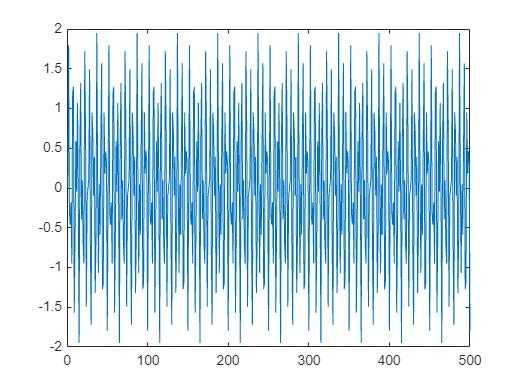

%LSP PART (a)
Fs = 50; 
N = 500;
f1 = 10; 
f2 = 17; 
missing_percentage = 0.1; 
SNR_dB = 10;
t = (0:N-1) / Fs;


signal = sin(2*pi*f1*t) + sin(2*pi*f2*t);
plot(signal);

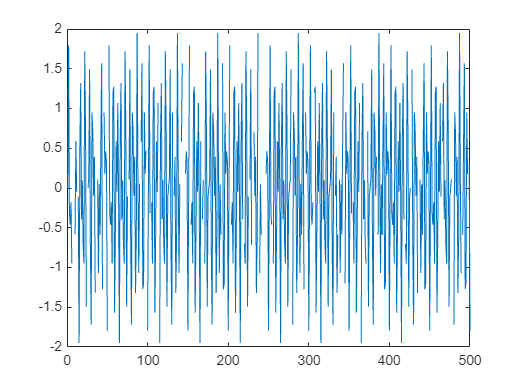

missing_data_indices = randperm(N, round(missing_percentage*N));
signal(missing_data_indices) = NaN;
plot(signal);

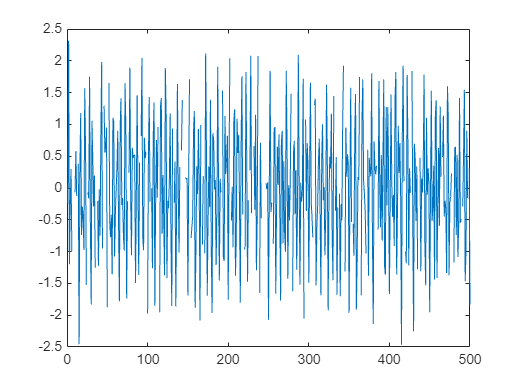


noise_power = nanvar(signal) / (10^(SNR_dB/10));

% Add noise to the signal
noise = sqrt(noise_power) * randn(size(signal));
noisy_signal = signal + noise;
plot(noisy_signal);

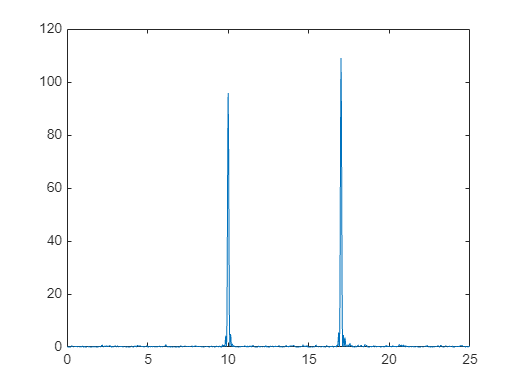


frequencies=linspace(1/Fs,Fs/2,1000);
[periodogram,ai,bi]=lomb_scargle_periodogram(noisy_signal,t,frequencies,0.01,1000);
plot(frequencies,periodogram);

%LSP part (b)
%Importing the tesla stock data in csv format
table_data = readtable('tesla_csv.csv');


%Encoding date to make it easier to inerpret
date=datenum(datetime(table_data.Date,"InputFormat","dd-MM-yyyy"));
date=date-date(1)+1;
charges=normalize(table_data.Close);


%Splitting the data into test and train 
trainRatio = 0.8;

% Create a random partition for training and testing
c = cvpartition(size(date, 1), 'HoldOut', 1 - trainRatio);

% Get indices for training and testing data
trainIdx = training(c); 
testIdx = test(c); 

% Split features into training and testing sets
Xtrain = date(trainIdx, :);
Xtest = date(testIdx, :);

% Split target into training and testing sets
Ytrain = charges(trainIdx);
Ytest = charges(testIdx);

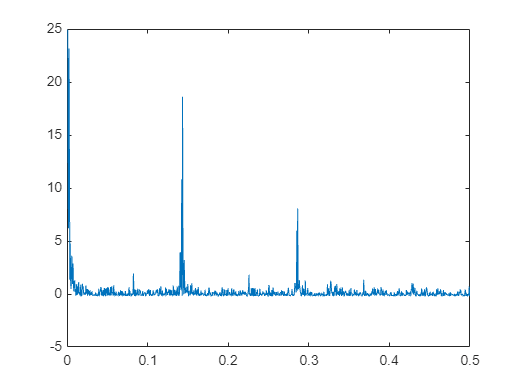

%Appying lomb scargle periodogram on train data
%(i)

frequencies=linspace(0.001,0.5,1000);

[periodogram,ai,bi]=lomb_scargle_periodogram(Ytrain,Xtrain,frequencies,0.01,1000);
plot(frequencies,periodogram);

%Parameters from the model
freq_1=frequencies(286);
freq_2=frequencies(572);
a_1=ai(286);
b_1=bi(286);
a_2=ai(572);
b_2=bi(572);

y_pred=a_1* cos(2*pi*freq_1 *Xtest) + b_1 * sin(2*pi*freq_1 * Xtest)+a_2* cos(2*pi*freq_2 *Xtest) + b_2 * sin(2*pi*freq_2 *Xtest);
Ytest;

%Calculating the evaluation metrics

% Calculate NMSE (Normalized Mean Square Error)
mse = mean((y_pred - Ytest).^2);
variance = var(Ytest);
nmse = mse / variance;
disp(['The Normalised Mean Square Error using Lomb Scargle Periodogram: ', num2str(nmse)]);

The Normalised Mean Square Error using Lomb Scargle Periodogram: 1.0009


%Calculaitng the mean absolute percentagre error
mape = mean(abs((y_pred - Ytest) ./ Ytest) * 100);
disp(['The Normalised Mean Absolute Percentage using Lomb Scargle Periodogram: ', num2str(mape)]);

The Normalised Mean Absolute Percentage using Lomb Scargle Periodogram: 100.1085


%Testing ARIMA MODEL
%(ii)
mdl = arima(2, 1, 1); % Specify the appropriate p, d, q values
EstMdl = estimate(mdl, Ytrain);

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    4.9232e-05      6.237e-05       0.78935      0.42991
    AR{1}           1.0251       0.022035        46.522            0
    AR{2}         -0.02514       0.017922       -1.4028      0.16069
    MA{1}         -0.96985       0.014511       -66.836            0
    Variance     0.0043211     5.4345e-05        79.512            0



Ypred = forecast(EstMdl, numel(Ytest), 'Y0', Ytest);
% Calculate NMSE (Normalized Mean Square Error)
mse = mean((Ypred - Ytest).^2);
variance = var(Ytest);
nmse = mse / variance;
disp(['The Normalised Mean Square Error using ARIMA(2,1,1) model: ', num2str(nmse)]);

The Normalised Mean Square Error using ARIMA(2,1,1) model: 524.7689


%Calculaitng the mean absolute percentagre error
mape = mean(abs((Ypred - Ytest) ./ Ytest) * 100);
disp(['The Mean Absolute Percentage using ARIMA(2,1,1) model: ', num2str(mape)]);

The Mean Absolute Percentage using ARIMA(2,1,1) model: 6378.1207


function [periodogram,ai,bi] = lomb_scargle_periodogram(y, t, frequencies, learning_rate, max_iterations)
    periodogram = zeros(size(frequencies));
    ai = zeros(size(frequencies));
    bi = zeros(size(frequencies));
    nan_indices = isnan(y);
    y(nan_indices) = 0; 
    
    for i =1: length(frequencies)
        for iter = 1:max_iterations
            f= frequencies(i);
            residual = y - (ai(i) * cos(2*pi*f * t) + bi(i) * sin(2*pi*f * t));
            gradient_a = -2 * sum(residual .* cos(2*pi*f * t));
            gradient_b = -2 * sum(residual .* sin(2*pi*f * t));
            ai(i) = ai(i) - learning_rate * gradient_a/1000;
            bi(i) = bi(i) - learning_rate * gradient_b/1000;
        end
        periodogram(i) = periodogram(i) +sum(residual.^2);
                
    
    
    end
    for iter = 1:max_iterations
            omega = 0;
            residual = y - (ai(i) * cos(omega * t) + bi(i) * sin(omega * t));
            gradient_a = -2 * sum(residual .* cos(omega * t));
            gradient_b = -2 * sum(residual .* sin(omega * t));
            ai(i) = ai(i) - learning_rate * gradient_a/1000;
            bi(i) = bi(i) - learning_rate * gradient_b/1000;
    end
    zero_chi_square=sum(residual.^2);
    for i =1:length(frequencies)
        periodogram(i)=(zero_chi_square-periodogram(i))/2;
    end
    y(nan_indices) = NaN;
end